# **Project Signal and Image Processing . Mod 1**

Project members:

- Tito Nicola Drugman, 502252, titonicola.drugman01@universitadipavia.it

- Angelica Pagni, 505887, angelica.pagni01@universitadipavia.it

rng(48);

subfolders = {'underexposed', 'correctly_exposed', 'overexposed'};
output_folder = 'gamma_corrected';

imageData = [];
labels = [];

% loop through each subfolder to read images
for i = 1:length(subfolders)
    folderPath = subfolders{i};
    
    imgFiles = dir(fullfile(folderPath, '*.jpg'));
    
    for j = 1:length(imgFiles)
        imgPath = fullfile(folderPath, imgFiles(j).name);
        
        img = imread(imgPath);
        
        % convert image to YCbCr and extract the Y channel
        imgYCbCr = rgb2ycbcr(img);
        Y = imgYCbCr(:,:,1);
        
        % calculate and normalize histogram
        histY = imhist(Y);
        histY = histY / sum(histY);
        
        % extract features: mean, variance, and skewness
        meanY = mean(histY);
        varY = var(histY);
        skewY = skewness(double(histY));

        % count pixels in the min and max bins
        minYValue = min(Y(:));  % min intensity value in Y channel
        maxYValue = max(Y(:));  % max intensity value in Y channel
        minBinCount = sum(Y(:) == minYValue); 
        maxBinCount = sum(Y(:) == maxYValue);

        imageData = [imageData; meanY, varY, skewY, minBinCount, maxBinCount];
        labels = [labels; i]; 
        % encoding: 1-underexposed, 2-correctly_exposed, 3-overexposed
    end
end


#### Train-test split

splitRatio = 0.8;  % 80% for training, 20% for testing
uniqueLabels = unique(labels);
numLabels = numel(uniqueLabels);
XTrain = [];
XTest = [];
YTrain = [];
YTest = [];

for i = 1:numLabels
    idx = find(labels == uniqueLabels(i));
    numDataPoints = numel(idx);
    numTrain = floor(splitRatio * numDataPoints);
    shuffledIndices = idx(randperm(numDataPoints));
    trainIdx = shuffledIndices(1:numTrain);
    testIdx = shuffledIndices(numTrain+1:end);
    XTrain = [XTrain; imageData(trainIdx,:)];
    YTrain = [YTrain; labels(trainIdx)];
    XTest = [XTest; imageData(testIdx,:)];
    YTest = [YTest; labels(testIdx)];
end


#### Normalize

%normalize the features
%min_vals = min(XTrain(:, 1:5), [], 1);
%max_vals = max(XTrain(:, 1:5), [], 1);
%XTrain(:, 1:5) = (XTrain(:, 1:5) - min_vals) ./ (max_vals - min_vals);
%XTest(:, 1:5) = (XTest(:, 1:5) - min_vals) ./ (max_vals - min_vals);

#### **KNN**

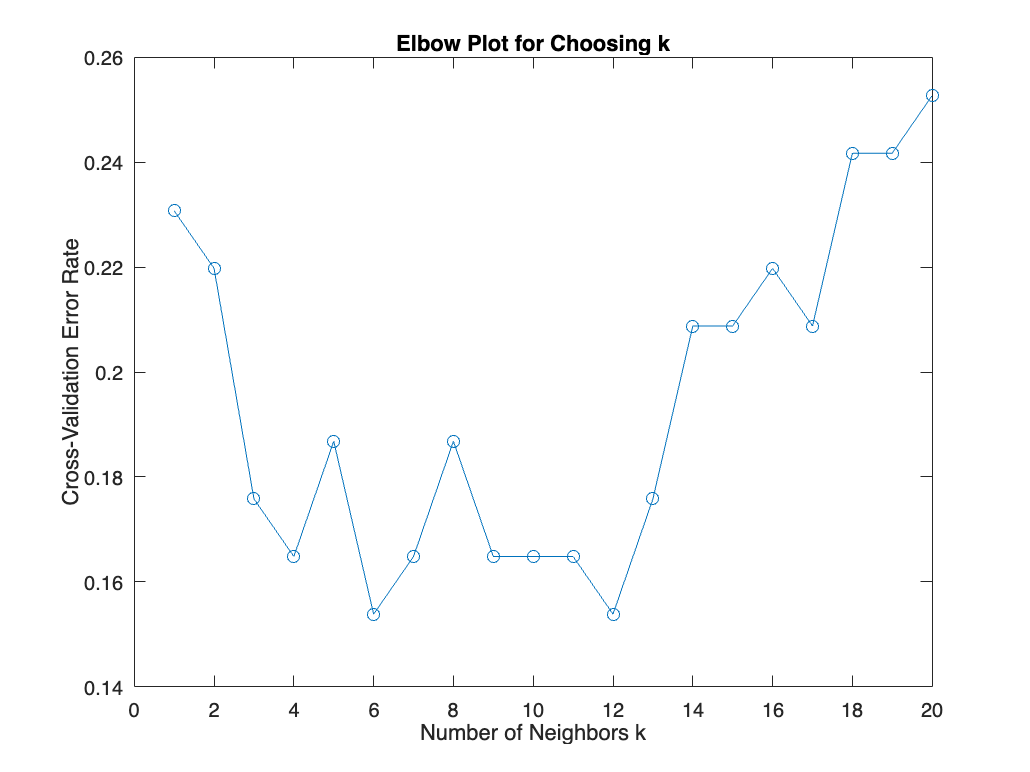

% KNN plot to find the optimal number of neighbors
kRange = 1:20;
errorRates = zeros(length(kRange), 1);

for k = kRange
    model = fitcknn(XTrain, YTrain, 'NumNeighbors', k, 'CrossVal', 'on');
    errorRates(k) = kfoldLoss(model);
end

figure;
plot(kRange, errorRates, '-o');
xlabel('Number of Neighbors k');
ylabel('Cross-Validation Error Rate');
title('Elbow Plot for Choosing k');


% optimal k
[~, optimalK] = min(errorRates);
disp(['Optimal number of neighbors: ', num2str(optimalK)]);

Optimal number of neighbors: 6



% ------------------------------------------

c = cvpartition(YTrain, 'KFold', 10);

% train KNN model with cross-validation using optimal NN
knnCVModel = fitcknn(XTrain, YTrain, 'CVPartition', c, 'NumNeighbors', optimalK);

% cross-validation loss for each fold
foldLosses = kfoldLoss(knnCVModel, 'Mode', 'individual');

% find fold with minimum loss
[~, bestFold] = min(foldLosses);
knncross = knnCVModel.Trained{bestFold};

% ------------------------------------------

% evaluate on training data and test data
predictedLabels = predict(knncross, XTrain);
accuracy = sum(predictedLabels == YTrain) / numel(YTrain);
disp(['Train Accuracy KNN: ', num2str(accuracy * 100), '%']);

Train Accuracy KNN: 84.6154%


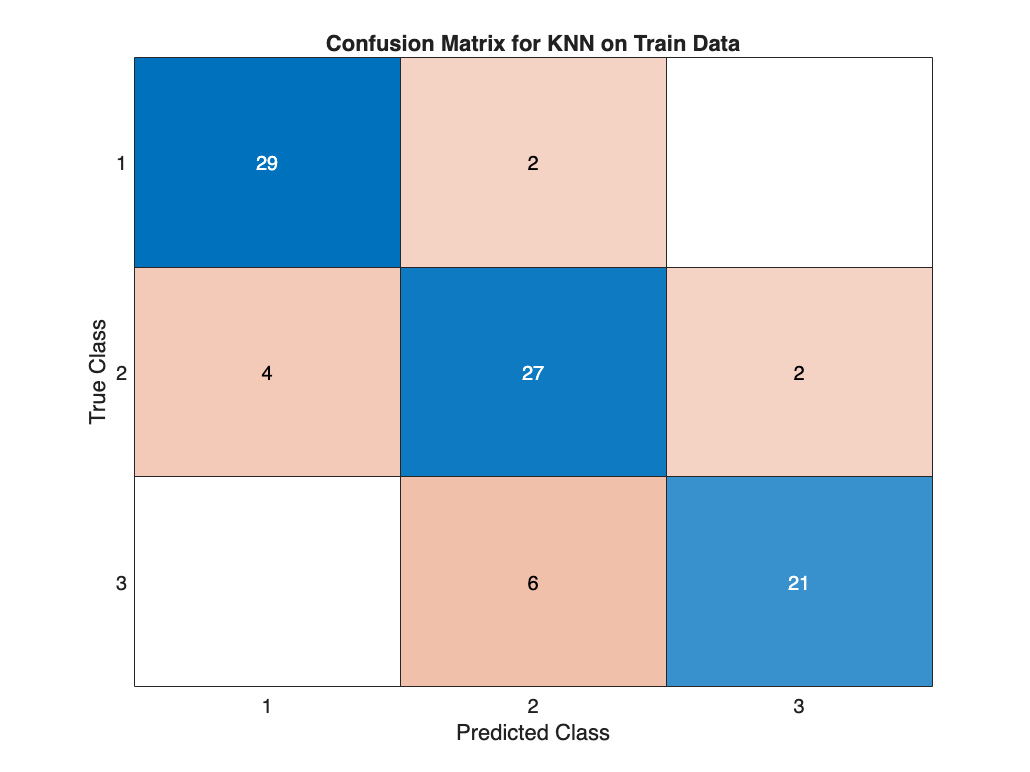

confusionchart(YTrain, predictedLabels, 'Title', 'Confusion Matrix for KNN on Train Data');


predictedLabels_test_knn = predict(knncross, XTest);
accuracy_test_knn = sum(predictedLabels_test_knn == YTest) / numel(YTest);
disp(['Test Accuracy KNN: ', num2str(accuracy_test_knn * 100), '%']);

Test Accuracy KNN: 79.1667%


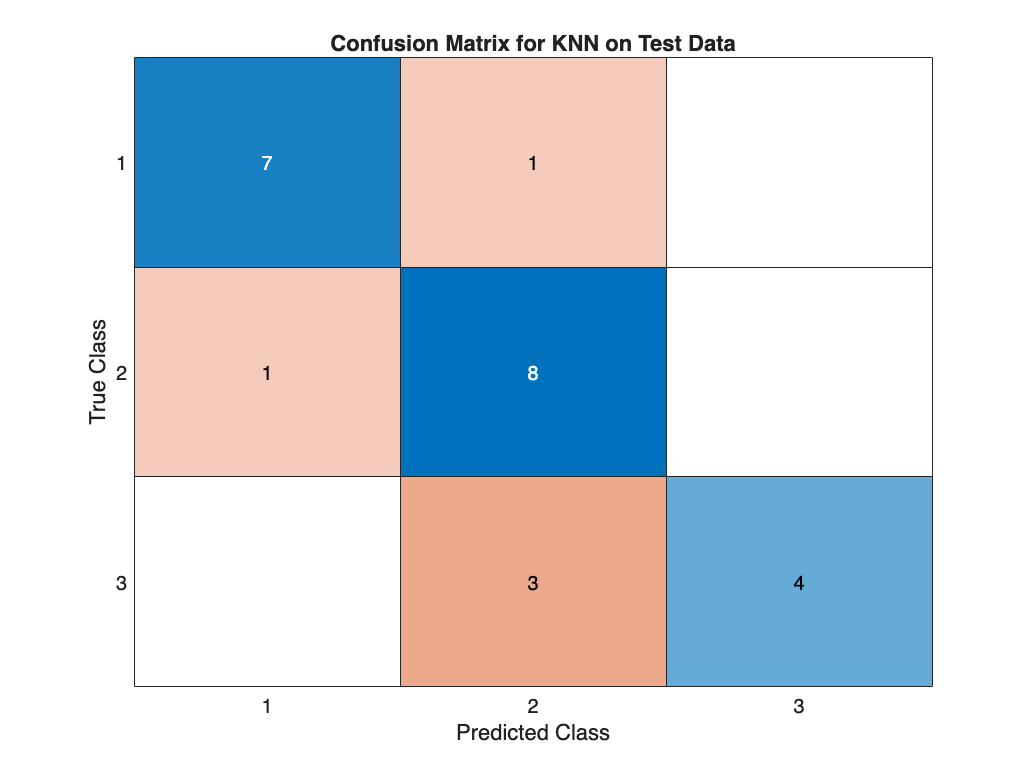

figure;
confusionchart(YTest, predictedLabels_test_knn, 'Title', 'Confusion Matrix for KNN on Test Data');

#### **Decision Tree**

c_tree = cvpartition(YTrain, 'KFold', 10);

% train Decision Tree model
treeCVModel = fitctree(XTrain, YTrain, 'CVPartition', c_tree);

% calculate cross-validation loss for each fold
foldLosses = kfoldLoss(treeCVModel, 'Mode', 'individual');

% find the fold with the minimum loss (best performance)
[~, bestFold] = min(foldLosses);
bestTreeModel = treeCVModel.Trained{bestFold};

% ------------------------------------------

% evaluate performance on training data and test data
predictedLabels_train_tree = predict(bestTreeModel, XTrain);
accuracy_tree = sum(predictedLabels_train_tree == YTrain) / numel(YTrain);
disp(['Train Accuracy tree: ', num2str(accuracy_tree * 100), '%']);

Train Accuracy tree: 93.4066%


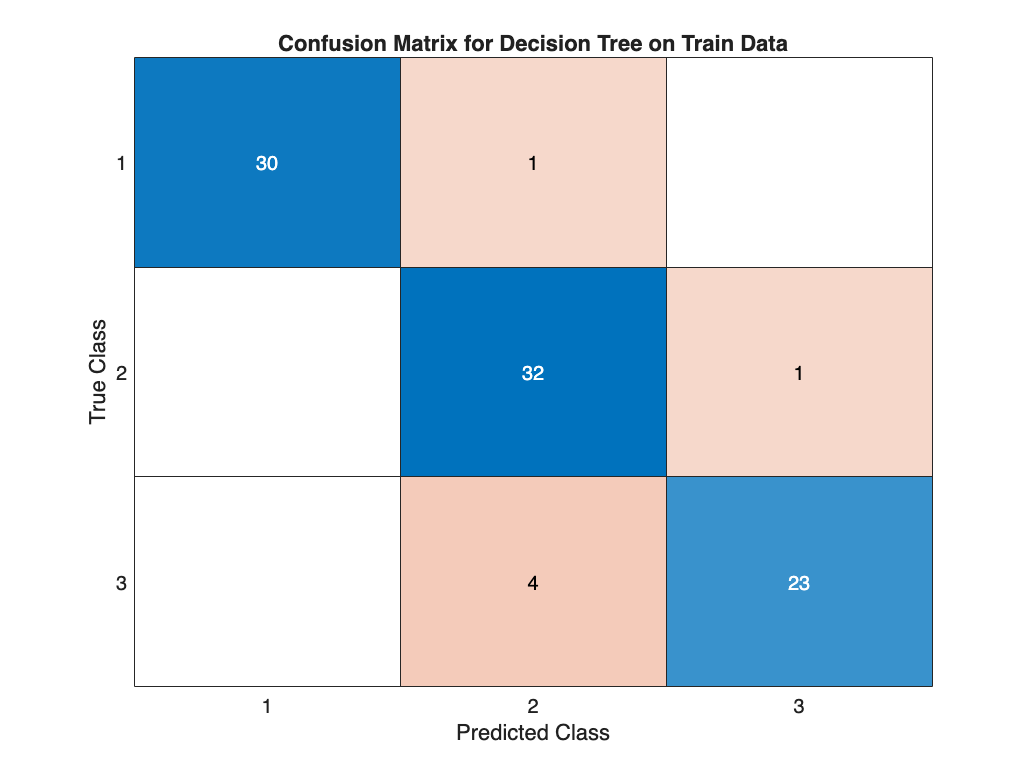

confusionchart(YTrain, predictedLabels_train_tree, 'Title', 'Confusion Matrix for Decision Tree on Train Data');


predictedLabels_test_tree = predict(bestTreeModel, XTest);
accuracy_test_tree = sum(predictedLabels_test_tree == YTest) / numel(YTest);
disp(['Test Accuracy Decision Tree: ', num2str(accuracy_test_tree * 100), '%']);

Test Accuracy Decision Tree: 87.5%


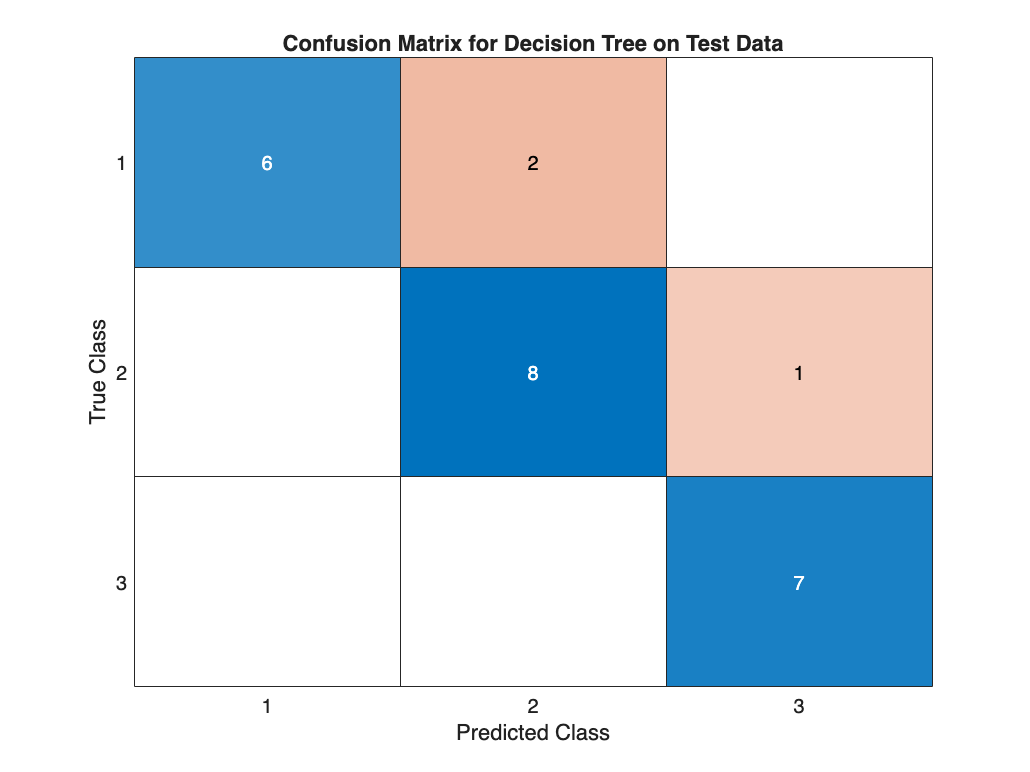

figure;
confusionchart(YTest, predictedLabels_test_tree, 'Title', 'Confusion Matrix for Decision Tree on Test Data');

Compute metrics for correctly exposed images

correctlyExposedFolderPath = fullfile(subfolders{2}, '*.jpg');

imgFiles = dir(correctlyExposedFolderPath);

numFiles = numel(imgFiles);
norm_means = zeros(numFiles, 1);
norm_vars = zeros(numFiles, 1);
norm_skew = zeros(numFiles, 1);
norm_minBins = zeros(numFiles, 1);
norm_maxBins = zeros(numFiles, 1);

for j = 1:numFiles
    imgPath = fullfile(imgFiles(j).folder, imgFiles(j).name);
    img = imread(imgPath);
    imgYCbCr = rgb2ycbcr(im2double(img));
    Y = imgYCbCr(:,:,1);
    
    % compute metrics
    norm_means(j) = mean(Y, 'all');
    norm_vars(j) = var(Y, 0, 'all');
    norm_skew(j) = skewness(double(Y(:)));
    minYValue = min(Y(:));
    maxYValue = max(Y(:));
    norm_minBins(j) = sum(Y(:) == minYValue);
    norm_maxBins(j) = sum(Y(:) == maxYValue);
end


target_mean = mean(norm_means);
target_variance = mean(norm_vars);
target_skew = mean(norm_skew);
target_minBinCount = mean(norm_minBins);
target_maxBinCount = mean(norm_maxBins);

% scale
norm_target_minBinCount = target_minBinCount / max(target_minBinCount, target_maxBinCount);
norm_target_maxBinCount = target_maxBinCount / max(target_minBinCount, target_maxBinCount);

disp(['Target Mean: ', num2str(target_mean)]);

Target Mean: 0.50782


disp(['Target Variance: ', num2str(target_variance)]);

Target Variance: 0.02893


disp(['Target Skewness: ', num2str(target_skew)]);

Target Skewness: -0.22396


disp(['Target Min Bin Count: ', num2str(norm_target_minBinCount)]);

Target Min Bin Count: 0.030701


disp(['Target Max Bin Count: ', num2str(norm_target_maxBinCount)]);

Target Max Bin Count: 1



target_minBinCount = norm_target_minBinCount;
target_maxBinCount = norm_target_maxBinCount;

disp('----------------------------');

----------------------------


disp('----- GAMMA CORRECTION -----');

----- GAMMA CORRECTION -----


disp('----------------------------');

----------------------------


function img_corrected = applyGammaCorrection(img, gamma)
    img_corrected = img .^ gamma;
end


function error = compute_gamma_error(gamma, img, target_mean, target_variance, target_skew, target_minBinCount, target_maxBinCount)
    img_corrected = applyGammaCorrection(img, gamma);
    mean_corrected = mean(img_corrected, 'all');
    var_corrected = var(img_corrected, 0, 'all');
    skew_corrected = skewness(double(img_corrected(:)));
    minYValue = min(img_corrected(:));
    maxYValue = max(img_corrected(:));
    minBinCount_corrected = sum(img_corrected(:) == minYValue);
    maxBinCount_corrected = sum(img_corrected(:) == maxYValue);
    error = (mean_corrected - target_mean)^2 + (var_corrected - target_variance)^2 + ...
            0.01*(skew_corrected - target_skew)^2 + 0.01*(minBinCount_corrected - target_minBinCount)^2 + ...
            0.01*(maxBinCount_corrected - target_maxBinCount)^2;
end


function best_gamma = find_best_gamma(img, target_mean, target_variance, target_skew, target_minBinCount, target_maxBinCount, lower_bound, upper_bound)
    gamma_init = 1;
    options = optimoptions('fmincon', 'Display', 'off');
    best_gamma = fmincon(@(gamma) compute_gamma_error(gamma, img, target_mean, target_variance, target_skew, target_minBinCount, target_maxBinCount), gamma_init, [], [], [], [], lower_bound, upper_bound, [], options);
end

if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end


for k = 1:length(subfolders)
    if ~exist(fullfile(output_folder, subfolders{k}), 'dir')
        mkdir(fullfile(output_folder, subfolders{k}));
    end
end


for i = 1:length(subfolders)
   folderPath = subfolders{i};
    imgFiles = dir(fullfile(folderPath, '*.jpg'));
    for j = 1:length(imgFiles)
        imgPath = fullfile(folderPath, imgFiles(j).name);
        img = im2double(imread(imgPath));
        img_ycbcr = rgb2ycbcr(img);
        img_y = img_ycbcr(:,:,1);
        Cb = img_ycbcr(:,:,2);
        Cr = img_ycbcr(:,:,3);
        
        % gamma bounds based on image type
        if i == 1  % underexposed
            gamma_lb = 0.1;
            gamma_ub = 1;
        elseif i == 2  % correctly_exposed
            gamma_lb = 0.8;
            gamma_ub = 1.2;
        else  % overexposed
            gamma_lb = 1.1;
            gamma_ub = 5;
        end
        
        best_gamma = find_best_gamma(img_y, target_mean, target_variance, target_skew, target_minBinCount, target_maxBinCount, gamma_lb, gamma_ub);
        y_corrected = applyGammaCorrection(img_y, best_gamma);
        img_recombined = cat(3, y_corrected, Cb, Cr);
        img_correct = ycbcr2rgb(img_recombined);
        [~, name, ext] = fileparts(imgPath);
        output_file = fullfile(output_folder, subfolders{i}, [name, '_correct', ext]);
        imwrite(im2uint8(img_correct), output_file);
    end
end


Evaluate

labels_correct = [];
filepaths_correct = [];
for i = 1:length(subfolders)
    files_correct = dir(fullfile(output_folder, subfolders{i}, '*.jpg'));

Starting image classification...


    filepaths_correct = [filepaths_correct; cellfun(@(s) fullfile(output_folder, subfolders{i}, s), {files_correct.name}', 'UniformOutput', false)];
    labels_correct = [labels_correct; repmat(i, length(files_correct), 1)];
end

features_correct = [];
for i = 1:numel(filepaths_correct)
    img = imread(filepaths_correct{i});
    imgYCbCr = rgb2ycbcr(im2double(img));
    Y = imgYCbCr(:,:,1);
    histY = imhist(Y);
    histY = histY / sum(histY);
    meanY = mean(histY);
    varY = var(histY);
    skewY = skewness(double(histY));
    minYValue = min(Y(:));
    maxYValue = max(Y(:));
    minBinCount = sum(Y(:) == minYValue);
    maxBinCount = sum(Y(:) == maxYValue);
    features_correct = [features_correct; meanY, varY, skewY, minBinCount, maxBinCount];
end

Processing underexposed...


KNN: IMG-20240702-WA0022_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0022_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0024_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0024_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0028_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0028_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0031_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0031_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0034_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0034_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0037_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0037_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0040_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0040_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0043_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0043_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0046_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0046_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0049_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0049_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0051_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0051_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0054_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0054_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0057_correct.jpg classified as overexposed


Decision Tree: IMG-20240702-WA0057_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0058_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0058_correct.jpg classified as overexposed


KNN: IMG-20240702-WA0063_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0063_correct.jpg classified as correctly_exposed


KNN: img11_correct.jpg classified as correctly_exposed


Decision Tree: img11_correct.jpg classified as correctly_exposed


KNN: img12_correct.jpg classified as correctly_exposed


Decision Tree: img12_correct.jpg classified as overexposed


KNN: img13_correct.jpg classified as correctly_exposed


Decision Tree: img13_correct.jpg classified as correctly_exposed


KNN: img14_correct.jpg classified as correctly_exposed


Decision Tree: img14_correct.jpg classified as correctly_exposed


KNN: img15_correct.jpg classified as correctly_exposed


Decision Tree: img15_correct.jpg classified as overexposed


KNN: img19_correct.jpg classified as correctly_exposed


Decision Tree: img19_correct.jpg classified as correctly_exposed


KNN: img1_correct.jpg classified as correctly_exposed


Decision Tree: img1_correct.jpg classified as correctly_exposed


KNN: img20_correct.jpg classified as correctly_exposed


Decision Tree: img20_correct.jpg classified as correctly_exposed


KNN: img25_correct.jpg classified as correctly_exposed


Decision Tree: img25_correct.jpg classified as correctly_exposed


KNN: img26_correct.jpg classified as overexposed


Decision Tree: img26_correct.jpg classified as overexposed


KNN: img27_correct.jpg classified as correctly_exposed


Decision Tree: img27_correct.jpg classified as correctly_exposed


KNN: img28_correct.jpg classified as correctly_exposed


Decision Tree: img28_correct.jpg classified as correctly_exposed


KNN: img29_correct.jpg classified as overexposed


Decision Tree: img29_correct.jpg classified as overexposed


KNN: img2_correct.jpg classified as correctly_exposed


Decision Tree: img2_correct.jpg classified as correctly_exposed


KNN: img30_correct.jpg classified as correctly_exposed


Decision Tree: img30_correct.jpg classified as correctly_exposed


KNN: img31_correct.jpg classified as correctly_exposed


Decision Tree: img31_correct.jpg classified as correctly_exposed


KNN: img32_correct.jpg classified as overexposed


Decision Tree: img32_correct.jpg classified as correctly_exposed


KNN: img33_correct.jpg classified as correctly_exposed


Decision Tree: img33_correct.jpg classified as correctly_exposed


KNN: img34_correct.jpg classified as correctly_exposed


Decision Tree: img34_correct.jpg classified as correctly_exposed


KNN: img35_correct.jpg classified as correctly_exposed


Decision Tree: img35_correct.jpg classified as correctly_exposed


KNN: img37_correct.jpg classified as correctly_exposed


Decision Tree: img37_correct.jpg classified as correctly_exposed


KNN: img38_correct.jpg classified as correctly_exposed


Decision Tree: img38_correct.jpg classified as correctly_exposed


KNN: img39_correct.jpg classified as correctly_exposed


Decision Tree: img39_correct.jpg classified as correctly_exposed


KNN: img8_correct.jpg classified as correctly_exposed


Decision Tree: img8_correct.jpg classified as overexposed


Processing correctly_exposed...


KNN: IMG-20240702-WA0023_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0023_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0026_correct.jpg classified as overexposed


Decision Tree: IMG-20240702-WA0026_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0029_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0029_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0032_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0032_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0035_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0035_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0038_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0038_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0041_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0041_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0044_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0044_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0047_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0047_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0050_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0050_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0053_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0053_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0056_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0056_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0060_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0060_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0061_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0061_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0065_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0065_correct.jpg classified as correctly_exposed


KNN: img10_correct.jpg classified as correctly_exposed


Decision Tree: img10_correct.jpg classified as overexposed


KNN: img12_correct.jpg classified as underexposed


Decision Tree: img12_correct.jpg classified as correctly_exposed


KNN: img13_correct.jpg classified as underexposed


Decision Tree: img13_correct.jpg classified as correctly_exposed


KNN: img14_correct.jpg classified as underexposed


Decision Tree: img14_correct.jpg classified as correctly_exposed


KNN: img15_correct.jpg classified as underexposed


Decision Tree: img15_correct.jpg classified as correctly_exposed


KNN: img18_correct.jpg classified as underexposed


Decision Tree: img18_correct.jpg classified as correctly_exposed


KNN: img19_correct.jpg classified as correctly_exposed


Decision Tree: img19_correct.jpg classified as correctly_exposed


KNN: img21_correct.jpg classified as correctly_exposed


Decision Tree: img21_correct.jpg classified as correctly_exposed


KNN: img24_correct.jpg classified as correctly_exposed


Decision Tree: img24_correct.jpg classified as correctly_exposed


KNN: img25_correct.jpg classified as correctly_exposed


Decision Tree: img25_correct.jpg classified as overexposed


KNN: img27_correct.jpg classified as correctly_exposed


Decision Tree: img27_correct.jpg classified as correctly_exposed


KNN: img29_correct.jpg classified as overexposed


Decision Tree: img29_correct.jpg classified as overexposed


KNN: img30_correct.jpg classified as correctly_exposed


Decision Tree: img30_correct.jpg classified as correctly_exposed


KNN: img31_correct.jpg classified as correctly_exposed


Decision Tree: img31_correct.jpg classified as correctly_exposed


KNN: img32_correct.jpg classified as underexposed


Decision Tree: img32_correct.jpg classified as correctly_exposed


KNN: img33_correct.jpg classified as correctly_exposed


Decision Tree: img33_correct.jpg classified as correctly_exposed


KNN: img34_correct.jpg classified as correctly_exposed


Decision Tree: img34_correct.jpg classified as correctly_exposed


KNN: img35_correct.jpg classified as underexposed


Decision Tree: img35_correct.jpg classified as correctly_exposed


KNN: img36_correct.jpg classified as underexposed


Decision Tree: img36_correct.jpg classified as correctly_exposed


KNN: img37_correct.jpg classified as underexposed


Decision Tree: img37_correct.jpg classified as correctly_exposed


KNN: img38_correct.jpg classified as correctly_exposed


Decision Tree: img38_correct.jpg classified as underexposed


KNN: img39_correct.jpg classified as correctly_exposed


Decision Tree: img39_correct.jpg classified as correctly_exposed


KNN: img4_correct.jpg classified as correctly_exposed


Decision Tree: img4_correct.jpg classified as correctly_exposed


KNN: img5_correct.jpg classified as correctly_exposed


Decision Tree: img5_correct.jpg classified as correctly_exposed


KNN: img6_correct.jpg classified as correctly_exposed


Decision Tree: img6_correct.jpg classified as correctly_exposed


KNN: img7_correct.jpg classified as correctly_exposed


Decision Tree: img7_correct.jpg classified as correctly_exposed


KNN: img8_correct.jpg classified as correctly_exposed


Decision Tree: img8_correct.jpg classified as correctly_exposed


Processing overexposed...


KNN: IMG-20240702-WA0025_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0025_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0027_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0027_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0030_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0030_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0033_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0033_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0036_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0036_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0039_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0039_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0042_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0042_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0045_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0045_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0048_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0048_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0052_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0052_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0055_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0055_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0059_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0059_correct.jpg classified as correctly_exposed


KNN: IMG-20240702-WA0062_correct.jpg classified as underexposed


Decision Tree: IMG-20240702-WA0062_correct.jpg classified as underexposed


KNN: IMG-20240702-WA0064_correct.jpg classified as correctly_exposed


Decision Tree: IMG-20240702-WA0064_correct.jpg classified as correctly_exposed


KNN: img10_correct.jpg classified as underexposed


Decision Tree: img10_correct.jpg classified as correctly_exposed


KNN: img13_correct.jpg classified as underexposed


Decision Tree: img13_correct.jpg classified as underexposed


KNN: img15_correct.jpg classified as underexposed


Decision Tree: img15_correct.jpg classified as underexposed


KNN: img16_correct.jpg classified as underexposed


Decision Tree: img16_correct.jpg classified as correctly_exposed


KNN: img1_correct.jpg classified as underexposed


Decision Tree: img1_correct.jpg classified as underexposed


KNN: img24_correct.jpg classified as underexposed


Decision Tree: img24_correct.jpg classified as underexposed


KNN: img25_correct.jpg classified as underexposed


Decision Tree: img25_correct.jpg classified as underexposed


KNN: img26_correct.jpg classified as underexposed


Decision Tree: img26_correct.jpg classified as underexposed


KNN: img28_correct.jpg classified as underexposed


Decision Tree: img28_correct.jpg classified as correctly_exposed


KNN: img29_correct.jpg classified as underexposed


Decision Tree: img29_correct.jpg classified as underexposed


KNN: img32_correct.jpg classified as underexposed


Decision Tree: img32_correct.jpg classified as underexposed


KNN: img33_correct.jpg classified as correctly_exposed


Decision Tree: img33_correct.jpg classified as correctly_exposed


KNN: img34_correct.jpg classified as correctly_exposed


Decision Tree: img34_correct.jpg classified as correctly_exposed


KNN: img35_correct.jpg classified as correctly_exposed


Decision Tree: img35_correct.jpg classified as correctly_exposed


KNN: img36_correct.jpg classified as correctly_exposed


Decision Tree: img36_correct.jpg classified as correctly_exposed


KNN: img37_correct.jpg classified as correctly_exposed


Decision Tree: img37_correct.jpg classified as correctly_exposed


KNN: img38_correct.jpg classified as correctly_exposed


Decision Tree: img38_correct.jpg classified as correctly_exposed


KNN: img39_correct.jpg classified as overexposed


Decision Tree: img39_correct.jpg classified as correctly_exposed


KNN: img3_correct.jpg classified as underexposed


Decision Tree: img3_correct.jpg classified as underexposed


KNN: img9_correct.jpg classified as correctly_exposed


Decision Tree: img9_correct.jpg classified as correctly_exposed


Final Results

knnCounts = zeros(3, 1);

Classification complete.


treeCounts = zeros(3, 1);

KNN Classification Results:


    33
    75
     7



disp('Starting image classification...');


Decision Tree Classification Results:


for i = 1:length(subfolders)

    17
    89
     9



    folderPath = fullfile(output_folder, subfolders{i});
    imgFiles = dir(fullfile(folderPath, '*.jpg'));

KNN Classification Summary:


Number of images classified as correctly exposed: 75


    disp(['Processing ', subfolders{i}, '...']);

Number of images classified as overexposed: 7


Number of images classified as underexposed: 33


    for j = 1:length(imgFiles)
        imgPath = fullfile(folderPath, imgFiles(j).name);

Decision Tree Classification Summary:


        img = imread(imgPath);

Number of images classified as correctly exposed: 89


        imgYCbCr = rgb2ycbcr(img);

Number of images classified as overexposed: 9


        Y = imgYCbCr(:,:,1);

Number of images classified as underexposed: 17


        
        histY = imhist(Y) / sum(imhist(Y));

-----------------------------


        meanY = mean(histY);

-------- BONUS POINT --------


        varY = var(histY);

-------- 1st apporach -------


        skewY = skewness(double(histY));

-----------------------------


        minYValue = min(Y(:));
        maxYValue = max(Y(:));
        minBinCount = sum(Y(:) == minYValue);
        maxBinCount = sum(Y(:) == maxYValue);
        features = [meanY, varY, skewY, minBinCount, maxBinCount];
        
        % KNN classification
        knnLabel = predict(knncross, features);
        knnCounts(knnLabel) = knnCounts(knnLabel) + 1;
        fprintf('KNN: %s classified as %s\n', imgFiles(j).name, subfolders{knnLabel});
        
        % Decision Tree classification
        treeLabel = predict(bestTreeModel, features);
        treeCounts(treeLabel) = treeCounts(treeLabel) + 1;
        fprintf('Decision Tree: %s classified as %s\n', imgFiles(j).name, subfolders{treeLabel});
    end
end


disp('Classification complete.');
disp('KNN Classification Results:');
disp(knnCounts);

disp('Decision Tree Classification Results:');
disp(treeCounts);

IMG-20240702-WA0022.jpg - Original NIQE: 3.880886, Corrected NIQE: 3.905780
IMG-20240702-WA0024.jpg - Original NIQE: 4.421346, Corrected NIQE: 4.440012
IMG-20240702-WA0028.jpg - Original NIQE: 4.921907, Corrected NIQE: 4.879202
IMG-20240702-WA0031.jpg - Original NIQE: 3.904665, Corrected NIQE: 4.506142
IMG-20240702-WA0034.jpg - Original NIQE: 5.112049, Corrected NIQE: 5.231965
IMG-20240702-WA0037.jpg - Original NIQE: 4.992699, Corrected NIQE: 5.184564
IMG-20240702-WA0040.jpg - Original NIQE: 4.846499, Corrected NIQE: 4.908783
IMG-20240702-WA0043.jpg - Original NIQE: 4.810751, Corrected NIQE: 4.754339
IMG-20240702-WA0046.jpg - Original NIQE: 4.481009, Corrected NIQE: 4.582852
IMG-20240702-WA0049.jpg - Original NIQE: 4.016109, Corrected NIQE: 4.143540
IMG-20240702-WA0051.jpg - Original NIQE: 4.418931, Corrected NIQE: 4.564013
IMG-20240702-WA0054.jpg - Original NIQE: 4.469673, Corrected NIQE: 4.484898
IMG-20240702-WA0057.jpg - Original NIQE: 4.299667, Corrected NIQE: 4.515714
IMG-20240702

disp('KNN Classification Summary:');
fprintf('Number of images classified as correctly exposed: %d\n', knnCounts(2));

Number of images with improved NIQE: 45 out of 115


fprintf('Number of images classified as overexposed: %d\n', knnCounts(3));
fprintf('Number of images classified as underexposed: %d\n', knnCounts(1));


Percentage of images with improved perceptual quality: 39.13%


disp('Decision Tree Classification Summary:');
fprintf('Number of images classified as correctly exposed: %d\n', treeCounts(2));

-----------------------------


fprintf('Number of images classified as overexposed: %d\n', treeCounts(3));

-------- BONUS POINT --------


fprintf('Number of images classified as underexposed: %d\n', treeCounts(1));

-------- 2nd apporach -------


disp('-----------------------------');

-----------------------------


disp('-------- BONUS POINT --------');
disp('-------- 1st apporach -------');
disp('-----------------------------');

niqe_scores_original = [];
niqe_scores_corrected = [];
improvement_count = 0;

for i = 1:length(subfolders)
    originalFolderPath = subfolders{i};
    correctedFolderPath = fullfile(output_folder, subfolders{i});
    
    originalImgFiles = dir(fullfile(originalFolderPath, '*.jpg'));
    correctedImgFiles = dir(fullfile(correctedFolderPath, '*.jpg'));
    
    for j = 1:length(originalImgFiles)
        originalImgPath = fullfile(originalFolderPath, originalImgFiles(j).name);
        correctedImgName = strrep(originalImgFiles(j).name, '.jpg', '_correct.jpg');
        correctedImgPath = fullfile(correctedFolderPath, correctedImgName);

        if exist(correctedImgPath, 'file')
            img_original = im2double(imread(originalImgPath));
            img_corrected = im2double(imread(correctedImgPath));
            
            original_niqe = niqe(img_original);
            corrected_niqe = niqe(img_corrected);

Desired Average Entropy: 7.341499


Desired Average Kurtosis: 2.901754


            niqe_scores_original = [niqe_scores_original; original_niqe];
            niqe_scores_corrected = [niqe_scores_corrected; corrected_niqe];

            if corrected_niqe < original_niqe
                improvement_count = improvement_count + 1;
            end
            
            fprintf('%s - Original NIQE: %f, Corrected NIQE: %f\n', originalImgFiles(j).name, original_niqe, corrected_niqe);
        else
            fprintf('Corrected image not found: %s\n', correctedImgPath);
        end
    end
end

total_images = length(niqe_scores_corrected);
fprintf('Number of images with improved NIQE: %d out of %d\n', improvement_count, total_images);

improvement_percentage = (improvement_count / total_images) * 100;
fprintf('Percentage of images with improved perceptual quality: %.2f%%\n', improvement_percentage);

File: IMG-20240702-WA0022.jpg


Entropy Before: 5.852791, After: 5.993950


Kurtosis Before: 2.621677, After: 3.375220


File: IMG-20240702-WA0024.jpg


Entropy Before: 5.376990, After: 5.490250


Kurtosis Before: 3.601264, After: 4.591066


File: IMG-20240702-WA0028.jpg


Entropy Before: 5.274485, After: 5.581996


Kurtosis Before: 1.805720, After: 1.891430


File: IMG-20240702-WA0031.jpg


Entropy Before: 4.763301, After: 5.268005


Kurtosis Before: 10.668817, After: 6.806195


File: IMG-20240702-WA0034.jpg


Entropy Before: 5.253133, After: 5.427970


Kurtosis Before: 3.628491, After: 4.164847


File: IMG-20240702-WA0037.jpg


Entropy Before: 4.874921, After: 5.181920


Kurtosis Before: 2.222826, After: 2.448236


File: IMG-20240702-WA0040.jpg


Entropy Before: 5.012913, After: 5.227319


Kurtosis Before: 4.499397, After: 6.013143


File: IMG-20240702-WA0043.jpg


Entropy Before: 5.868937, After: 5.979437


Kurtosis Before: 2.398634, After: 2.528797


File: IMG-20240702-WA0046.jpg


Entropy Before: 5.917778, After: 6.118015


Kurtosis Before: 7.907488, After: 5.126669


File: IMG-20240702-WA0049.jpg


Entropy Before: 5.996696, After: 6.157711


Kurtosis Before: 2.416991, After: 2.729328


File: IMG-20240702-WA0051.jpg


Entropy Before: 5.544875, After: 5.793458


Kurtosis Before: 13.295061, After: 7.821021


File: IMG-20240702-WA0054.jpg


Entropy Before: 5.259738, After: 5.699870


Kurtosis Before: 6.249124, After: 4.455271


File: IMG-20240702-WA0057.jpg


Entropy Before: 6.402786, After: 6.613680


Kurtosis Before: 2.023790, After: 1.683464


File: IMG-20240702-WA0058.jpg


Entropy Before: 6.122913, After: 6.189079


Kurtosis Before: 14.450236, After: 7.146068


File: IMG-20240702-WA0063.jpg


Entropy Before: 4.769043, After: 4.874077


Kurtosis Before: 6.466660, After: 6.962424


File: img1.jpg


Entropy Before: 6.261443, After: 6.477824


Kurtosis Before: 1.796222, After: 1.755170


File: img11.jpg


Entropy Before: 6.344929, After: 6.600959


Kurtosis Before: 6.610034, After: 3.849122


File: img12.jpg


Entropy Before: 5.823728, After: 5.982450


Kurtosis Before: 9.443453, After: 3.267547


File: img13.jpg


Entropy Before: 6.562053, After: 6.672362


Kurtosis Before: 2.779451, After: 2.055755


File: img14.jpg


Entropy Before: 5.461994, After: 5.871466


Kurtosis Before: 3.008570, After: 2.239606


File: img15.jpg


Entropy Before: 5.621420, After: 5.871202


Kurtosis Before: 20.377873, After: 4.912260


File: img19.jpg


Entropy Before: 5.604880, After: 5.926515


Kurtosis Before: 2.400788, After: 1.900112


File: img2.jpg


Entropy Before: 5.557801, After: 5.768281


Kurtosis Before: 1.549492, After: 1.499915


File: img20.jpg


Entropy Before: 5.152422, After: 5.330660


Kurtosis Before: 4.798603, After: 2.926399


File: img25.jpg


Entropy Before: 5.641919, After: 6.017405


Kurtosis Before: 5.963815, After: 4.464755


File: img26.jpg


Entropy Before: 6.567799, After: 6.613218


Kurtosis Before: 10.450691, After: 4.888727


File: img27.jpg


Entropy Before: 5.382264, After: 5.540807


Kurtosis Before: 3.029250, After: 3.563513


File: img28.jpg


Entropy Before: 5.182328, After: 5.513094


Kurtosis Before: 5.590864, After: 3.703015


File: img29.jpg


Entropy Before: 6.385328, After: 6.351211


Kurtosis Before: 8.555310, After: 5.234314


File: img30.jpg


Entropy Before: 5.842811, After: 6.091731


Kurtosis Before: 4.107055, After: 3.210364


File: img31.jpg


Entropy Before: 6.120935, After: 6.329188


Kurtosis Before: 2.329751, After: 2.224626


File: img32.jpg


Entropy Before: 7.176206, After: 7.188640


Kurtosis Before: 2.034253, After: 1.804649


File: img33.jpg


Entropy Before: 5.949585, After: 6.043028


Kurtosis Before: 1.347242, After: 1.249411


File: img34.jpg


Entropy Before: 4.057834, After: 4.489283


Kurtosis Before: 16.333946, After: 12.476384


File: img35.jpg


Entropy Before: 6.820647, After: 6.891656


Kurtosis Before: 1.633271, After: 1.656331


File: img37.jpg


Entropy Before: 6.321628, After: 6.434378


Kurtosis Before: 1.189132, After: 1.209155


File: img38.jpg


Entropy Before: 6.332264, After: 6.445936


Kurtosis Before: 1.461115, After: 1.455146


File: img39.jpg


Entropy Before: 6.530569, After: 6.724030


Kurtosis Before: 6.036804, After: 2.984971


File: img8.jpg


Entropy Before: 6.137960, After: 6.194554


Kurtosis Before: 11.047255, After: 7.327304


File: IMG-20240702-WA0023.jpg


Entropy Before: 7.379780, After: 7.467988


Kurtosis Before: 3.227124, After: 2.934454


File: IMG-20240702-WA0026.jpg


Entropy Before: 7.032249, After: 7.128946


Kurtosis Before: 4.355580, After: 3.870211


File: IMG-20240702-WA0029.jpg


Entropy Before: 7.286447, After: 7.271493


Kurtosis Before: 2.062579, After: 2.088563


File: IMG-20240702-WA0032.jpg


Entropy Before: 7.016490, After: 7.035809


Kurtosis Before: 3.765748, After: 3.495361


File: IMG-20240702-WA0035.jpg


Entropy Before: 6.994351, After: 7.029026


Kurtosis Before: 4.007345, After: 3.846024


File: IMG-20240702-WA0038.jpg


Entropy Before: 6.813101, After: 6.830390


Kurtosis Before: 2.718570, After: 2.709822


File: IMG-20240702-WA0041.jpg


Entropy Before: 6.873232, After: 6.935915


Kurtosis Before: 6.056899, After: 5.373508


File: IMG-20240702-WA0044.jpg


Entropy Before: 7.125989, After: 7.099738


Kurtosis Before: 2.188307, After: 2.281163


File: IMG-20240702-WA0047.jpg


Entropy Before: 7.413877, After: 7.366222


Kurtosis Before: 3.044025, After: 2.889486


File: IMG-20240702-WA0050.jpg


Entropy Before: 7.549739, After: 7.619864


Kurtosis Before: 2.348080, After: 2.218618


File: IMG-20240702-WA0053.jpg


Entropy Before: 7.309356, After: 7.305213


Kurtosis Before: 3.641825, After: 3.689264


File: IMG-20240702-WA0056.jpg


Entropy Before: 7.795790, After: 7.795729


Kurtosis Before: 1.910903, After: 1.910789


File: IMG-20240702-WA0060.jpg


Entropy Before: 7.181877, After: 7.156604


Kurtosis Before: 3.779969, After: 3.828454


File: IMG-20240702-WA0061.jpg


Entropy Before: 7.655906, After: 7.646593


Kurtosis Before: 1.398567, After: 1.417687


File: IMG-20240702-WA0065.jpg


Entropy Before: 6.681183, After: 6.763327


Kurtosis Before: 7.491910, After: 6.873147


File: img10.jpg


Entropy Before: 7.694504, After: 7.696649


Kurtosis Before: 2.312457, After: 2.310516


File: img12.jpg


Entropy Before: 7.241292, After: 7.307457


Kurtosis Before: 2.431026, After: 2.244382


File: img13.jpg


Entropy Before: 7.822392, After: 7.831179


Kurtosis Before: 1.841072, After: 1.841438


File: img14.jpg


Entropy Before: 7.619292, After: 7.618956


Kurtosis Before: 2.058350, After: 2.057390


File: img15.jpg


Entropy Before: 7.352590, After: 7.352613


Kurtosis Before: 2.537156, After: 2.536913


File: img18.jpg


Entropy Before: 7.521841, After: 7.573052


Kurtosis Before: 1.836094, After: 1.712975


File: img19.jpg


Entropy Before: 7.884117, After: 7.849232


Kurtosis Before: 1.746999, After: 1.732019


File: img21.jpg


Entropy Before: 7.329321, After: 7.283210


Kurtosis Before: 3.245348, After: 3.149586


File: img24.jpg


Entropy Before: 6.917942, After: 6.918481


Kurtosis Before: 3.512095, After: 3.512542


File: img25.jpg


Entropy Before: 7.747956, After: 7.705599


Kurtosis Before: 2.721685, After: 2.585344


File: img27.jpg


Entropy Before: 7.016036, After: 7.060299


Kurtosis Before: 3.984167, After: 3.446638


File: img29.jpg


Entropy Before: 7.719325, After: 7.722338


Kurtosis Before: 2.244502, After: 2.243832


File: img30.jpg


Entropy Before: 7.675243, After: 7.649763


Kurtosis Before: 2.141504, After: 2.134456


File: img31.jpg


Entropy Before: 7.652320, After: 7.652173


Kurtosis Before: 2.071630, After: 2.045032


File: img32.jpg


Entropy Before: 7.572325, After: 7.552300


Kurtosis Before: 2.743317, After: 2.368640


File: img33.jpg


Entropy Before: 7.409284, After: 7.364097


Kurtosis Before: 1.598484, After: 1.547056


File: img34.jpg


Entropy Before: 6.665231, After: 6.624742


Kurtosis Before: 5.583943, After: 5.257143


File: img35.jpg


Entropy Before: 7.688103, After: 7.699824


Kurtosis Before: 1.766044, After: 1.705478


File: img36.jpg


Entropy Before: 7.423673, After: 7.422093


Kurtosis Before: 1.407104, After: 1.380184


File: img37.jpg


Entropy Before: 7.628640, After: 7.608669


Kurtosis Before: 1.531837, After: 1.443935


File: img38.jpg


Entropy Before: 6.968815, After: 7.004277


Kurtosis Before: 1.536791, After: 1.493204


File: img39.jpg


Entropy Before: 7.658482, After: 7.666796


Kurtosis Before: 1.641161, After: 1.580328


File: img4.jpg


Entropy Before: 7.778323, After: 7.781281


Kurtosis Before: 1.869212, After: 1.880458


File: img5.jpg


Entropy Before: 6.909359, After: 6.851768


Kurtosis Before: 4.606276, After: 4.353655


File: img6.jpg


Entropy Before: 6.922219, After: 6.913119


Kurtosis Before: 4.402954, After: 4.347654


File: img7.jpg


Entropy Before: 6.965542, After: 6.966136


Kurtosis Before: 3.409538, After: 3.399302


File: img8.jpg


Entropy Before: 7.449433, After: 7.418026


Kurtosis Before: 3.095499, After: 3.145044


File: IMG-20240702-WA0025.jpg


Entropy Before: 5.362200, After: 6.009268


Kurtosis Before: 11.490008, After: 7.561884


File: IMG-20240702-WA0027.jpg


Entropy Before: 5.477689, After: 5.622062


Kurtosis Before: 3.191516, After: 2.233324


File: IMG-20240702-WA0030.jpg


Entropy Before: 7.669052, After: 7.688023


Kurtosis Before: 2.996009, After: 3.032724


File: IMG-20240702-WA0033.jpg


Entropy Before: 6.806307, After: 7.337793


Kurtosis Before: 7.419890, After: 3.449207


File: IMG-20240702-WA0036.jpg


Entropy Before: 6.707891, After: 7.100683


Kurtosis Before: 3.245324, After: 2.739654


File: IMG-20240702-WA0039.jpg


Entropy Before: 6.561325, After: 7.207241


Kurtosis Before: 6.391606, After: 3.612551


File: IMG-20240702-WA0042.jpg


Entropy Before: 6.760973, After: 7.213502


Kurtosis Before: 2.897808, After: 1.831878


File: IMG-20240702-WA0045.jpg


Entropy Before: 7.448186, After: 7.487940


Kurtosis Before: 2.984482, After: 3.065789


File: IMG-20240702-WA0048.jpg


Entropy Before: 4.300470, After: 4.876541


Kurtosis Before: 4.805696, After: 3.738848


File: IMG-20240702-WA0052.jpg


Entropy Before: 6.280692, After: 7.122232


Kurtosis Before: 7.222053, After: 2.495105


File: IMG-20240702-WA0055.jpg


Entropy Before: 5.157346, After: 5.774853


Kurtosis Before: 2.369418, After: 2.009678


File: IMG-20240702-WA0059.jpg


Entropy Before: 4.140669, After: 4.466448


Kurtosis Before: 1.689197, After: 1.496316


File: IMG-20240702-WA0062.jpg


Entropy Before: 6.184884, After: 6.786718


Kurtosis Before: 5.258829, After: 3.498820


File: IMG-20240702-WA0064.jpg


Entropy Before: 6.761156, After: 6.850947


Kurtosis Before: 8.463568, After: 5.371459


File: img1.jpg


Entropy Before: 5.529793, After: 6.035903


Kurtosis Before: 7.746104, After: 5.428856


File: img10.jpg


Entropy Before: 7.082011, After: 7.358574


Kurtosis Before: 2.506676, After: 1.802527


File: img13.jpg


Entropy Before: 5.661195, After: 5.972191


Kurtosis Before: 2.328716, After: 1.577517


File: img15.jpg


Entropy Before: 6.354024, After: 6.579448


Kurtosis Before: 2.215675, After: 1.474276


File: img16.jpg


Entropy Before: 7.109905, After: 7.443516


Kurtosis Before: 1.816291, After: 1.622918


File: img24.jpg


Entropy Before: 3.203539, After: 3.932380


Kurtosis Before: 8.874162, After: 7.356168


File: img25.jpg


Entropy Before: 4.199050, After: 5.030343


Kurtosis Before: 5.997876, After: 4.638101


File: img26.jpg


Entropy Before: 4.596796, After: 5.150683


Kurtosis Before: 4.901364, After: 3.699422


File: img28.jpg


Entropy Before: 6.896679, After: 7.353151


Kurtosis Before: 4.778826, After: 3.031709


File: img29.jpg


Entropy Before: 4.899033, After: 5.184862


Kurtosis Before: 3.143767, After: 2.283323


File: img3.jpg


Entropy Before: 6.068055, After: 6.555881


Kurtosis Before: 4.146524, After: 2.948114


File: img32.jpg


Entropy Before: 6.497520, After: 6.857223


Kurtosis Before: 3.015591, After: 1.654807


File: img33.jpg


Entropy Before: 5.509605, After: 5.530238


Kurtosis Before: 2.700859, After: 1.598981


File: img34.jpg


Entropy Before: 6.465218, After: 6.425248


Kurtosis Before: 5.801966, After: 5.316840


File: img35.jpg


Entropy Before: 7.296126, After: 7.535968


Kurtosis Before: 3.036497, After: 2.700128


File: img36.jpg


Entropy Before: 6.107121, After: 6.355487


Kurtosis Before: 2.072370, After: 1.430801


File: img37.jpg


Entropy Before: 7.182883, After: 7.641842


Kurtosis Before: 3.493271, After: 2.356650


File: img38.jpg


Entropy Before: 7.112011, After: 7.594447


Kurtosis Before: 2.629882, After: 2.173193


File: img39.jpg


Entropy Before: 7.108924, After: 7.359004


Kurtosis Before: 2.750256, After: 2.834465


File: img9.jpg


Entropy Before: 7.196257, After: 7.496897


Kurtosis Before: 2.776226, After: 2.997075


disp('-----------------------------');
disp('-------- BONUS POINT --------');
disp('-------- 2nd apporach -------');
disp('-----------------------------');

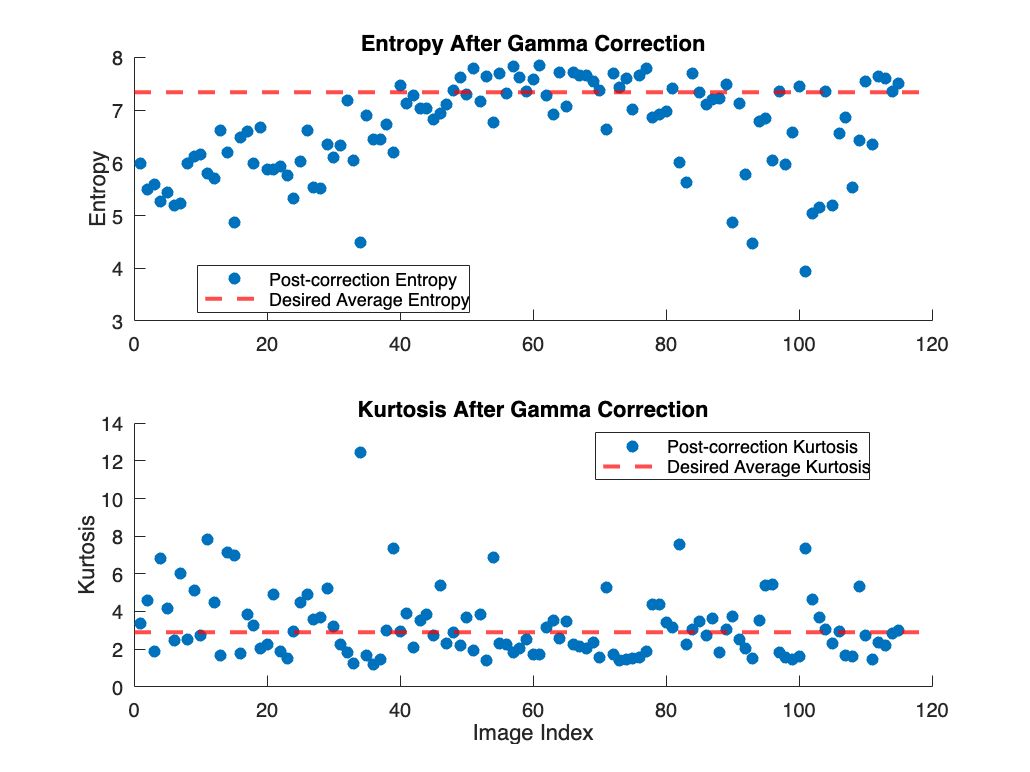

folderPath = subfolders{2};
imgFiles = dir(fullfile(folderPath, '*.jpg'));

entropy_values = zeros(length(imgFiles), 1);
kurtosis_values = zeros(length(imgFiles), 1);

function [entropy_val, kurtosis_val] = compute_metrics(img)
    img_double = im2double(img); 
    img_flattened = img_double(:); 

    entropy_val = entropy(img_flattened);
    kurtosis_val = kurtosis(img_flattened);
end


for i = 1:length(imgFiles)
    imgPath = fullfile(folderPath, imgFiles(i).name);
    img = imread(imgPath);

    [entropy_values(i), kurtosis_values(i)] = compute_metrics(img);
end

average_entropy = mean(entropy_values);
average_kurtosis = mean(kurtosis_values);

fprintf('Desired Average Entropy: %f\n', average_entropy);
fprintf('Desired Average Kurtosis: %f\n', average_kurtosis);

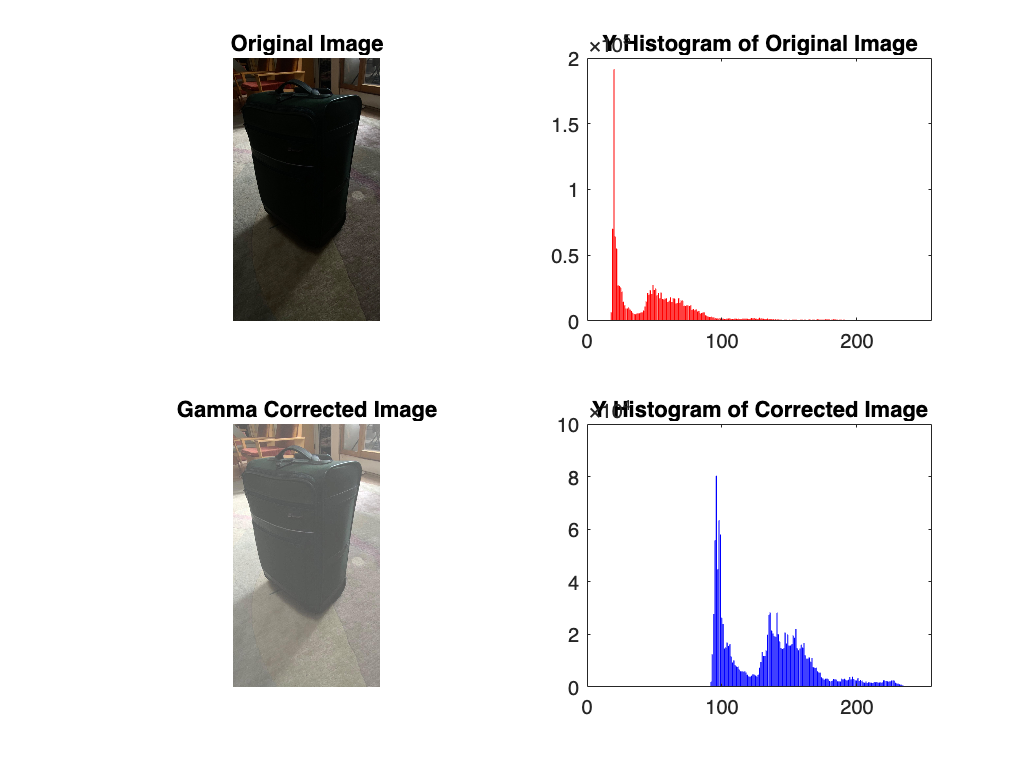

entropy_after_values = [];

kurtosis_after_values = [];

entropy_after_values = [];
kurtosis_after_values = [];
output_folder = 'gamma_corrected';
for i = 1:length(subfolders)
    folderPath = subfolders{i};
    imgFiles = dir(fullfile(folderPath, '*.jpg'));
    for j = 1:length(imgFiles)
        imgPath = fullfile(folderPath, imgFiles(j).name);
        img = imread(imgPath);

        [entropy_before, kurtosis_before] = compute_metrics(img);

        % apply gamma correction
        %img_corrected = applyGammaCorrection(im2double(img), 2.2); % test
        correctedImagePath = fullfile(output_folder, subfolders{i}, [imgFiles(j).name(1:end-4), '_correct.jpg']);
        img_corrected = imread(correctedImagePath);

        [entropy_after, kurtosis_after] = compute_metrics(img_corrected);

        entropy_after_values(end+1) = entropy_after;
        kurtosis_after_values(end+1) = kurtosis_after;

        fprintf('File: %s\n', imgFiles(j).name);
        fprintf('Entropy Before: %f, After: %f\n', entropy_before, entropy_after);
        fprintf('Kurtosis Before: %f, After: %f\n', kurtosis_before, kurtosis_after);
    end
end


Plot entropy and kurtosis

figure;
subplot(2,1,1); 
scatter(1:length(entropy_after_values), entropy_after_values, 'filled');
hold on;
yline(average_entropy, 'r--', 'LineWidth', 2);
ylabel('Entropy');
title('Entropy After Gamma Correction');
legend('Post-correction Entropy', 'Desired Average Entropy', 'Location', 'best');

subplot(2,1,2);
scatter(1:length(kurtosis_after_values), kurtosis_after_values, 'filled');
hold on;
yline(average_kurtosis, 'r--', 'LineWidth', 2);
ylabel('Kurtosis');
title('Kurtosis After Gamma Correction');
legend('Post-correction Kurtosis', 'Desired Average Kurtosis', 'Location', 'best');

xlabel('Image Index');

Check results

function plotImageAndHistogram(output_folder, subfolder, imageName)
    originalImagePath = fullfile(subfolder, imageName);
    correctedImagePath = fullfile(output_folder, subfolder, [imageName(1:end-4), '_correct.jpg']);

    originalImg = imread(originalImagePath);
    correctedImg = imread(correctedImagePath);

    originalYCbCr = rgb2ycbcr(originalImg);
    correctedYCbCr = rgb2ycbcr(correctedImg);

    originalY = originalYCbCr(:,:,1);
    correctedY = correctedYCbCr(:,:,1);

    originalYHist = imhist(originalY);
    correctedYHist = imhist(correctedY);

    figure;
    subplot(2, 2, 1);
    imshow(originalImg);
    title('Original Image');

    subplot(2, 2, 2);
    bar(originalYHist, 'r');
    title('Y Histogram of Original Image');
    xlim([0 256]); 

   
    subplot(2, 2, 3);
    imshow(correctedImg);
    title('Gamma Corrected Image');

    subplot(2, 2, 4);
    bar(correctedYHist, 'b');
    title('Y Histogram of Corrected Image');
    xlim([0 256]); 
end

plotImageAndHistogram(output_folder, 'underexposed', 'img39.jpg');